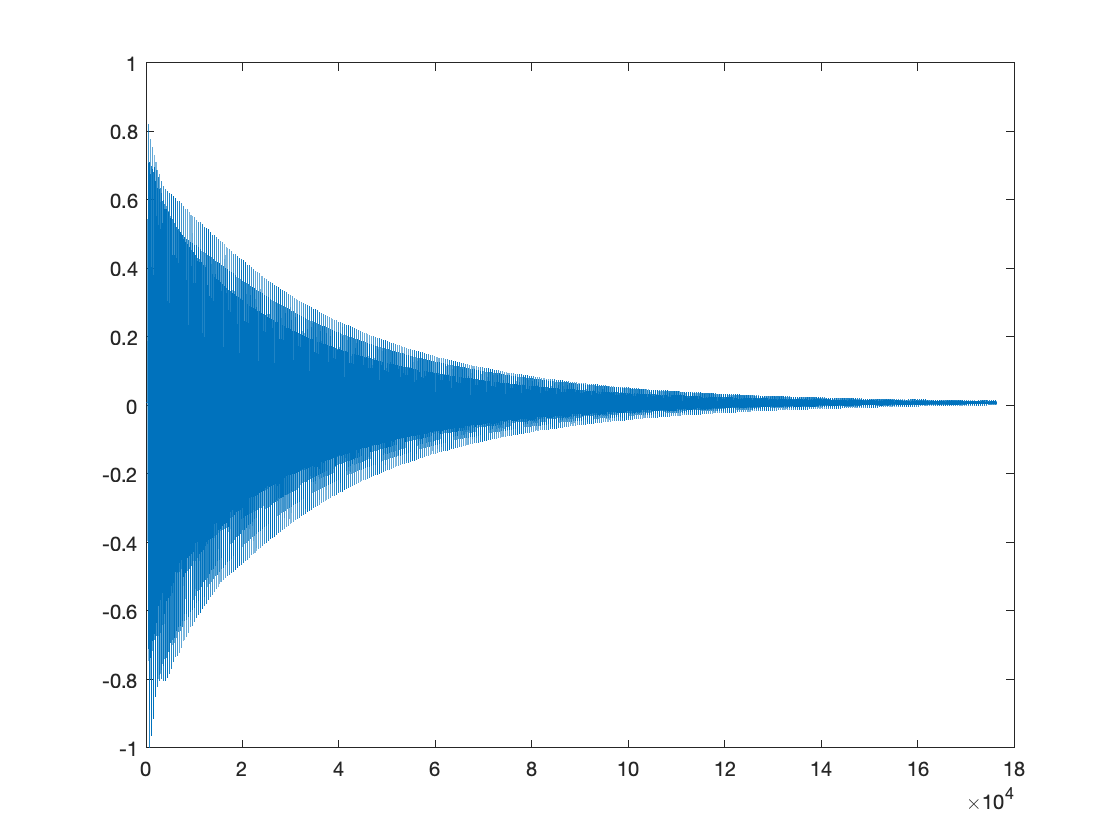

%%Implementation of the karplus-Strong Algorithm
%%A circular buffer simulates the delay-line
%%For every iteration of the loop 

%%DECLARING INITIAL VARIABLES AND CONDITIONS

%Sampling Frequency, Fs = 44100 samples per second
Fs = 44100;
%Frequency of the Plucked String, A = 100 Hz
A = 110;
%APF Gain
g = 0.1;
%Loss factor to incorporate decay of harmonics. Loss factor implemented as
%(1-a) to analyse the acceptable loss factor
a = 0.01;

%x is the input vector, total 4 seconds of sound
x = zeros(1, Fs*4);
%Number of samples of linear delay, calaculated based on the string
%frequency
delay = round(Fs/A);
%A short burst of white noise (1% of samples per second) is generated as
%input to the system
wh = randn(Fs*0.01, 1);

%%ALGORITHM IMPLEMENTATION WITH CIRCULAR BUFFER

%% First few samples of the input vector changed to white noise
x(1:length(wh)) = wh;

%%Passing input through LPF - dynamics filter
R = 0.9; 
for n = 1:length(x)
    if (n<2)
        x2(n) = x(n);
    else
        x2(n) = (1 - R) * x(n) + R * x2(n-1);
    end
end
x = x2;

%Length of buffer decides maximum possible delay
buffer = zeros(delay,1); 

%Input signal declared as in, for processing in the circular buffer
in = x;

N = length(in); %Loop counter
out = zeros(N,1);%output vector, initialised with all zeros

%%According to the x and y notation in difference equations, the vector
%%'in' represents x, and the array 'out' represents y
for n = 1:N
    
   %Implementation without all pass filtering
%     if n>1
%         [out(n), buffer] = circularBuffer(in(n) + LPout(n-1), buffer, delay, n);
%     else
%         [out(n), buffer] = circularBuffer(in(n), buffer, delay, n);
%     end
%     

  %Slur effect (hammer on) - Change delay and buffer length 
%     fret = 5;
%     d1 = round(Fs/(A*2^(fret/12)));
    %d1 is the new vallue of delat. Each successive fret is higher than the
    %previous one by a factor of 2^(1/12), and this is factored in when the
    %new delay is caluclated based on a given fret position. (N/5)
    %indicates that the hammer-on willl occur when a 5 sth of the audio has
    %passed
%     if n == floor(N/5)
%         delay = d1;
%     end

 %Implementation with all pass filtering
    if n>1
        [out(n), buffer] = circularBuffer(in(n) + out2(n-1), buffer, delay, n);
    else
        [out(n), buffer] = circularBuffer(in(n), buffer, delay, n);
    end
    
    %Low-Pass Filter - LPout is the output of the low-pass filter at time
    %n, which is then added to the input of the buffer at each iteration
    %except the first
    if (n)>1
        %LPout(n) = (out(n) + out(n-1) ) / 2;
        %LPout(n) = (1-a) * (out(n) + out(n-1) ) / 2;
        LPout(n) = (1-a) * (0.9 * out(n) + 0.1 * out(n-1) );
        %LPout(n) = (0.9 * out(n) + 0.1 * out(n-1) );
    else
        LPout(n) = out(n);
    end
    
    %All-Pass Filter
    if (n)>1
        out2(n) = (-g * LPout(n)) + LPout(n-1) + (g * out2(n-1));
    else
        out2(n) = LPout(n);
    end    
    
end



%out is assigned to out2 for further processing. This was done to avoid a
%memory segmentation error that is received when further processing s done
%on the same array. 


%%AMPLITUDE MODULATION AND DISTORTION EFFECTS

%%A Tremolo effect is achieved my modulating the amplitude of the carrier
%%wave by the means of a LFO (Low-Frequency Oscillator).

%Tremolo Parameters

% %DEPTH is the intensity of the effect, always calculated as a percentage.
% depth = 60;
% 
% %SPEED of the wave. Essentially, Frequency of the LFO.
% speed = 5;
% 
% %Sampling period calculated as the inverse of sampling frequency
% Ts = 1/Fs;
% 
% %Weighted amplitude, affected by the depth of tremolo effect
% amp = 0.5 * (depth/100);
% 
% %Calculating DC Offset
% offset = 1 - amp;
% 
% %LFO Synthesis
% f = speed;
% phi = 0;
% t = (1:length(out)) * Ts;
% t = t';
% LFO = sin(2*pi*f*t + phi);
% 
% %Modulating Wave
% mod = amp .* LFO + offset;
% 
% %Applying LFO to Carrier wave
% out = out .* mod;


%Normalizing synthesized output to ensure that it is centered around 0

out = out - mean(out);
out = out/max(abs(out));

%Plotting and playing the synthesized sound

plot(out);

soundsc(out,Fs);

%audiowrite('/Users/devansh/Desktop/SoundProcessing/StringTremolo.wav',out,44100);

function [out,buffer] = circularBuffer(in, buffer, delay, n)
%This function will implement a circular buffer
    %%Determine indexes for circular buffer
    len = length(buffer);
    indexC = mod(n-1,len) + 1; %Current Index in circular buffer
    indexD = mod(n-delay-1, len) + 1; %Delay index in circular buffer
    
    out = buffer(indexD);
    
    %Store the current output in appropriate index 
    buffer(indexC) = in;
end




